# Fastest Descent

## Analytical solution:

Ref: [https://en.wikipedia.org/wiki/Brachistochrone_curve](https://en.wikipedia.org/wiki/Brachistochrone_curve)


$$\begin{array}{l}
x=r\left(\;\;\;\varphi -\;\sin \varphi \right)\\
y=r\left(-1+\cos \varphi \right)
\end{array}$$


initial condition is $\left(x,y\right)=\left(0,0\right)$ i.e. $\varphi =0$

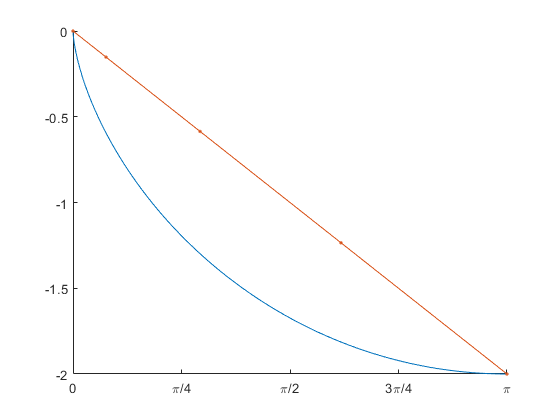

r = 1;
phi = linspace(0,2*pi,200+1);
x_exact = r*(phi-sin(phi))';
y_exact = r*( -1+cos(phi))';

% stay inside the spline by a tolerance
x_eps = 1e-5;  % stay inside x < pi-x_eps 
y_eps = 1e-5;  % start at y = - y_eps;

% initial guess
N = 4;
% x_spline = linspace(0,pi,N+1)';
% y_spline = -2/pi*x_spline;
x_spline = ( (1-cos([0:N]/N*pi/2))*pi )';
y_spline = -2/pi*x_spline;

figure(101); clf;
hold on
plot(x_exact ,y_exact )
plot(x_spline,y_spline,'.-')
ax = gca;
ax.XTick = [0:4]/4*pi;
ax.XTickLabel = ["0","\pi/4","\pi/2","3\pi/4","\pi"];
ax.XLim = [0,pi];
ax.YTick = [-2:0.5:0];

*Copyright 2021 The MathWorks, Inc.*